# ME5554/AOE5754/ECE5754 Applied Linear Systems

# Homework 1

name

date

This purpose of this homework is to refresh your basic understanding of some pre-requisite material:

- transfer functions

- closed-loop analysis

- Laplace transforms

- time-domain simulation

- linear algebra

Some of these problems can be completed in multiple ways.  You are welcome to use whichever way works best for you; however, this course is Matlab intensive, and you will be required to complete some future assignments using advanced tools such as LiveScripting and the Symbolic Toolbox.  If you are not comfortable using some of these Matlab tools, I highly recommend you spend time with the following:

Matlab LiveScript

- watch the Matlab LiveScript Tutorial video in the Course Gallery on Canvas (most important)

- [https://www.mathworks.com/products/matlab/live-editor.html](https://www.mathworks.com/products/matlab/live-editor.html)

Matlab Symbollic Toolbox

- see the symbolic_examples.mlx file on the Matlab Tutorials page linked from the Canvas Home page

- [https://www.mathworks.com/help/matlab/live-scripts-and-functions.html?s_tid=CRUX_lftnav](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html?s_tid=CRUX_lftnav)

- https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html

## Problem 1.

An open-loop plant is given by:  $P\left(s\right)=\left\lbrack \frac{\omega^2 }{s^2 +2\zeta \omega s+\omega^2 }\right\rbrack$.  Assuming a conventional unity negative feedback loop, use algebra to solve for the feedback compensator $C\left(s\right)$ such that the closed-loop transfer function is exactly: $\frac{y\left(s\right)}{r\left(s\right)}=T=\left\lbrack \frac{b\;}{s\left(s+a\right)}\right\rbrack$.  Demonstrate that your result is correct.

syms s zeta omega b a C_s
P_s = omega^2 / (s^2 + 2*zeta*omega*s + omega^2);
T_s = b / (s * (s + a)); %Required Transfer Function
T_eqn = (P_s * C_s) / (1 + P_s * C_s); %Conversion from open loop to unit negative feedback loop
eqn = T_s == T_eqn; %Forming the equation in symbolic toolbox
[C_s_solution,params,conds] = solve(eqn, C_s, 'ReturnConditions',true);
verification = simplify((C_s_solution*P_s)/(1+P_s*C_s_solution));
%Verification
fprintf('The C(s) result is correct because substituting that into T_eqn variable yields %s \n', char(verification))

The C(s) result is correct because substituting that into T_eqn variable yields b/(s*(a + s)) 


## Problem 2.

Derive an analytic solution (i.e. not numerical) for the unit **impulse** response of the closed-loop system from Problem 1 assuming zero initial conditions.

h_t = ilaplace(T_s); %Since the inverse laplace of TF is the impulse response of the system
fprintf('The analytic expression for impulse response is: %s \n', char(h_t))

The analytic expression for impulse response is: b/a - (b*exp(-a*t))/a 


## Problem 3.

Substitute a value of $a=0\ldotp 5$ and $b=1\ldotp 0$ into the analytic result from Problem 2 and compute a numerical solution for the step response.  Also use the Matlab STEP function to numerically compute the step response of the closed-loop system.  What is the DC Gain of the closed-loop system?  Compare the two numerical response results on a properly annotated single figure.

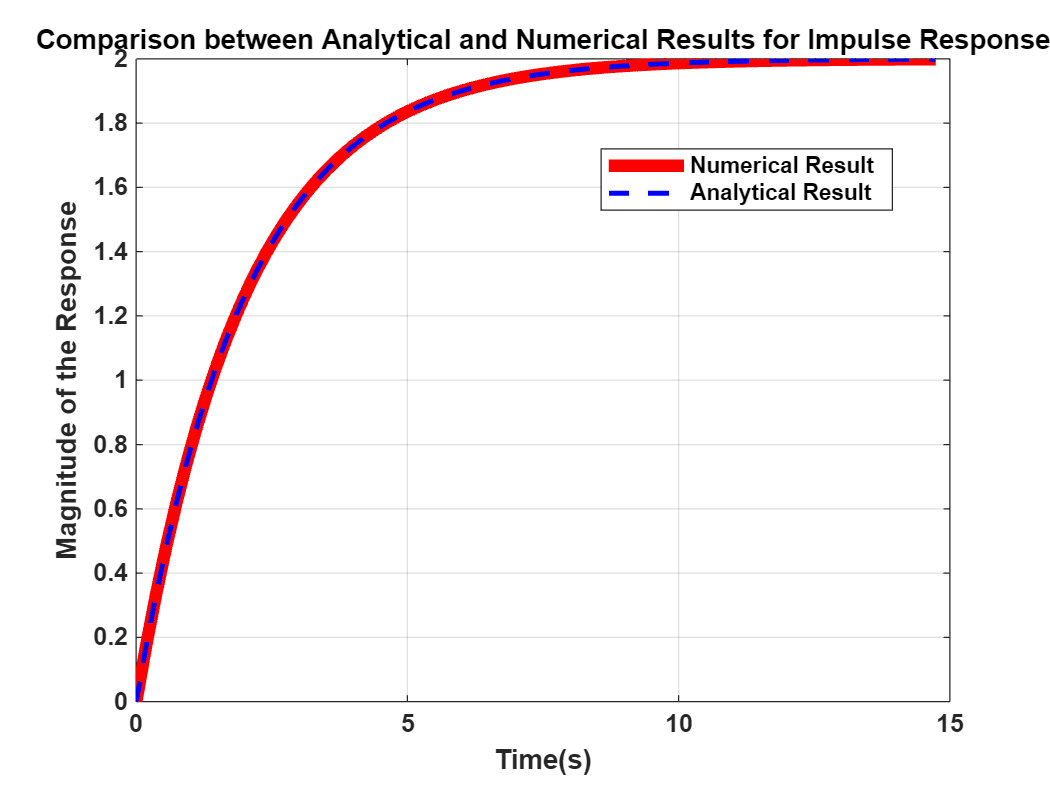

analyticResult = subs(T_s, [a b], [0.5 1.0]);
%constant values
a = 0.5;
b = 1.0;

num = [0 0 b]; % b
den = [1 a 0]; %s^2+sa
sys = tf(num, den); %Transfer Function
[numerical_impulse, time] = impulse(sys);

%defining the analytical expression for impulse response
syms t b a
h_t = b/a-(b*exp(-a*t))/a;
analytic_impulse = zeros(size(time));

for i = 1:length(time)
    analytic_impulse(i) = double(subs(h_t, [t b a], [time(i) 1.0 0.5]));
end

figure(1)
h(1) = plot(time, numerical_impulse, 'Color', 'r','LineWidth', 5);
hold on
h(2) = plot(time, analytic_impulse, 'Color', 'b','LineWidth', 2, 'LineStyle', '--');
grid on
title('Comparison between Analytical and Numerical Results for Impulse Response')
xlabel('Time(s)', 'FontSize',5)
ylabel('Magnitude of the Response')
set(gca,'FontSize', 10, 'FontWeight', 'bold')
legend(h, 'Numerical Result', 'Analytical Result', 'Location', 'best')

DC_gain = dcgain(sys);
disp(['DC Gain of the closed-loop system is: ', num2str(DC_gain)]);

DC Gain of the closed-loop system is: Inf


## Problem 4.

a)  Given the matrix:  $\mathbf{A}=\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & c & 0\\
0 & d & e
\end{array}\right\rbrack$, determine an **analytic** expression (i.e. not numerical) for the determinant of $\mathbf{A}$ 

syms a b c d e s
A = [a b 0;0 c 0;0 d e]; %A matrix definition
det_A = det(A); %Determinant of A
pretty(det_A)

a c e



b)  Determine an analytic expression for the determinant of $\left\lbrack s\;I-A\right\rbrack$

eigen_matrix = eye(3).*s-A;
pretty(eigen_matrix)

/ s - a,   -b,    0   \
|                     |
|   0,   s - c,   0   |
|                     |
\   0,     -d,  s - e /



c)  Explain what kind of information each of these determinants provides.

If the determinant of the aforementioned matrix is equated to 0, then eigen values can be obtained which later be used to form the eigen vectors.

## Problem 5.

An "Elementary Permutation Matrix" is a matrix that contains only 1's and 0's, and there can only be one 1 in any row or column.  This kind of matrix is used to swap rows or swap columns in another matrix when it is multiplied by that matrix.

a)  Use visual inspection to determine an "Elementary Left Permutation Matrix" ${\mathbf{P}}_L$ such that the product ${\mathbf{P}}_L \mathbf{A}$ swaps rows 2 and 3 of the $\mathbf{A}$ matrix.


$${\mathbf{P}}_L \mathbf{A}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & c & 0\\
0 & d & e
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & d & e\\
0 & c & 0
\end{array}\right\rbrack$$


b)  Use visual inspection to determine a "Elementary Right Permutation Matrix" ${\mathbf{P}}_R$ such that the product $\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R$ swaps columns 2 and 3 of the ${\mathbf{P}}_L \mathbf{A}$ matrix.


$$\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R =\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & d & e\\
0 & c & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
a & 0 & b\\
0 & e & d\\
0 & 0 & c
\end{array}\right\rbrack$$


c)  Compute the determinants of ${\mathbf{P}}_R$ and ${\mathbf{P}}_L$

left_elementary_matrix = [1 0 0;0 0 1;0 1 0];
right_elementary_matrix = [1 0 0;0 0 1;0 1 0];
det_PLA = det(left_elementary_matrix)

det_PLA = -1

det_PRA = det(right_elementary_matrix)

det_PRA = -1

d)  Compute the determinant of $\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R$

PLA = left_elementary_matrix * A;
PLA_PR = PLA*right_elementary_matrix;
det_PLA_PRA = det(PLA_PR)

$$det\_PLA\_PRA = a\,c\,e$$

e)  Compare the result from 5d) to the product $\left|{\mathbf{P}}_L \right|\times \left|\mathbf{A}\right|\times \left|{\mathbf{P}}_R \right|$

PLA_PRA_mod = det(left_elementary_matrix)*det(A)*right_elementary_matrix

$$PLA\_PRA\_mod = \left(\begin{array}{ccc} -a\,c\,e & 0 & 0\\ 0 & 0 & -a\,c\,e\\ 0 & -a\,c\,e & 0 \end{array}\right)$$